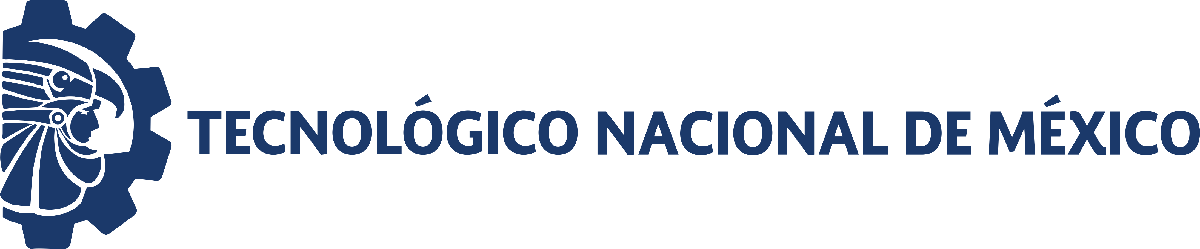                                 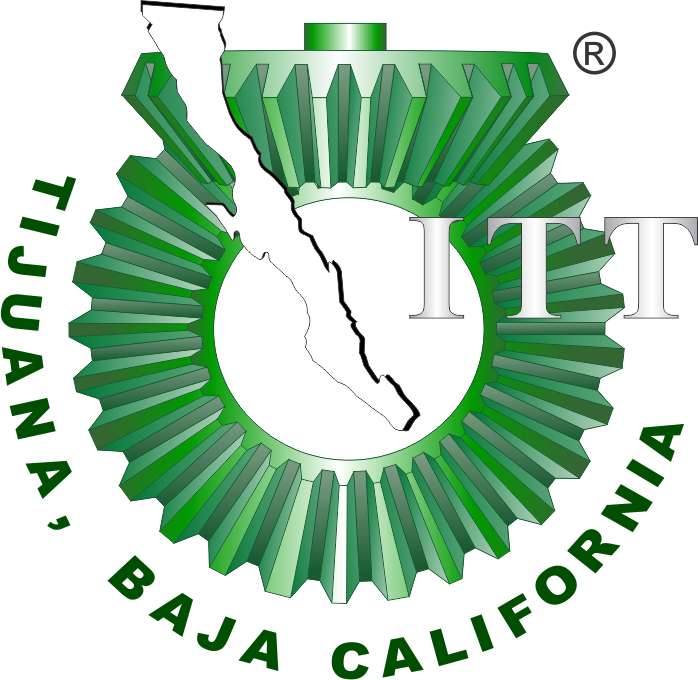

# Práctica: Liberación controlada de fármacos por hidrogeles

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

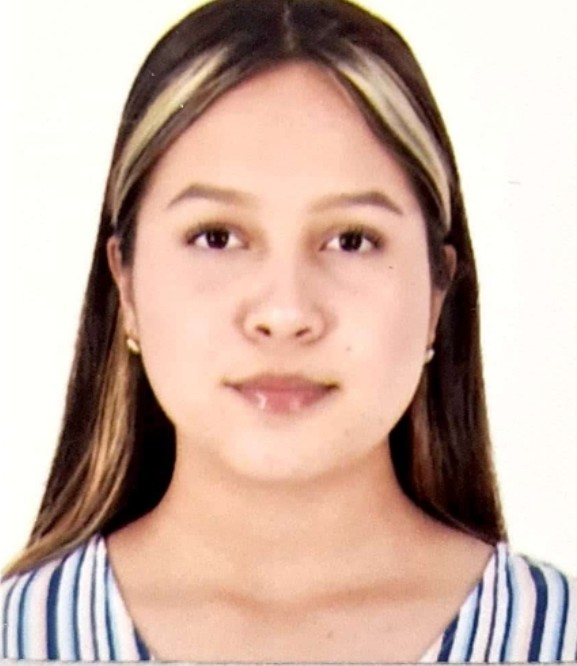

Nombre del alumno: **Sofía Cristina Durán Muñoz**

Número de control: **22211752**

Correo institucional: **l22211752@tectijuana.edu.mx**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Objetivo

Determinar la tasa de liberación del hidrogel N36 2MBA3 con base en los datos experimentales de la siguiente figura.

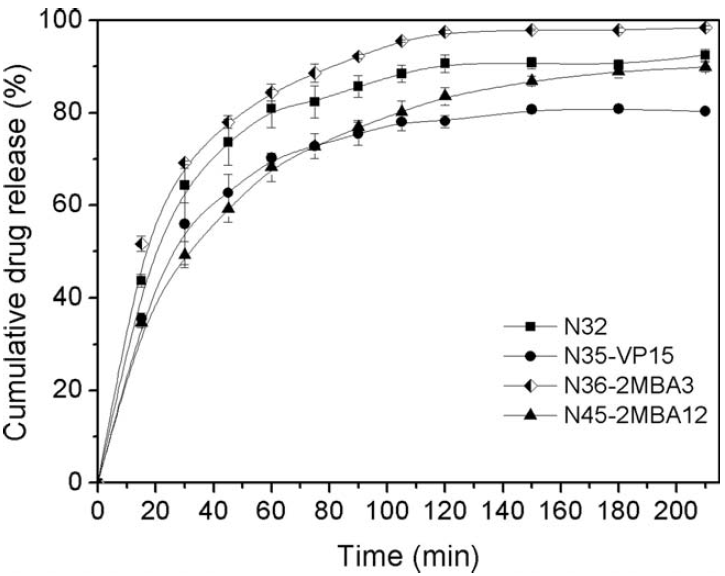

## Referencia

M. A. González‐Ayón, J.A. Sañudo‐Barajas, L.A. Picos‐Corrales, & A. Licea‐Claverie, "PNVCL‐PEGMA nanohydrogels with tailored transition temperature for controlled delivery of 5‐fluorouracil", *Journal of Polymer Science Part A: Polymer Chemistry*, vol. 53, issue 22, pp. 2662-2672, Aug 2015. DOI: [https://doi.org/10.1002/pola.27766](https://doi.org/10.1002/pola.27766)

## Modelos a ajustar a los datos experimentales

Ecuación de Peppas: $x\left(t\right)=kt^n$

Farmacocinética de primer orden: $$x(t) = \beta(1 - e^{-kt})$ $

Eureqa: $x(t)$ = $rho_1*sqrt(t) - rho_2t$

Eureqa EDO: $\overset{\ldotp }{x} ={rho}_1 -{rho}_2 x$

## Datos experimentales

clc; clear; close all; warning('off')
sys = readmatrix('dataS.csv');
t = round(sys(:,1)); %tiempo
x1 = sys(:,2); %N45-2MBA12
x2 = sys(:,3); %N32
x3 = sys(:,4); %N35-VP15
x4 = sys(:,5); %N36-2MBA3

T = table(t,x1,x2,x3,x4);
T.Properties.VariableNames = {'t [min]', 'N45', 'N32', 'N35', 'N36'};
disp(T);

    t [min]     N45       N32       N35       N36  
    _______    ______    ______    ______    ______

        0           0         0         0         0
       15      34.772    43.719    35.788     51.92
       30      49.421    64.669    55.929    69.361
       45      59.822    73.623    63.057    77.892
       60      68.557    81.157    70.387    84.617
       75      73.047    82.803    73.045    88.899
       90      76.719    85.861    76.318    92.164
      105      80.792    88.721     78.16    95.636
      120      83.863    90.971    78.518    97.489
      150      87.145    91.217    80.842    98.123
      180      89.411    90.637    81.079    98.352
      210      90.053    92.497    80.299    98.582



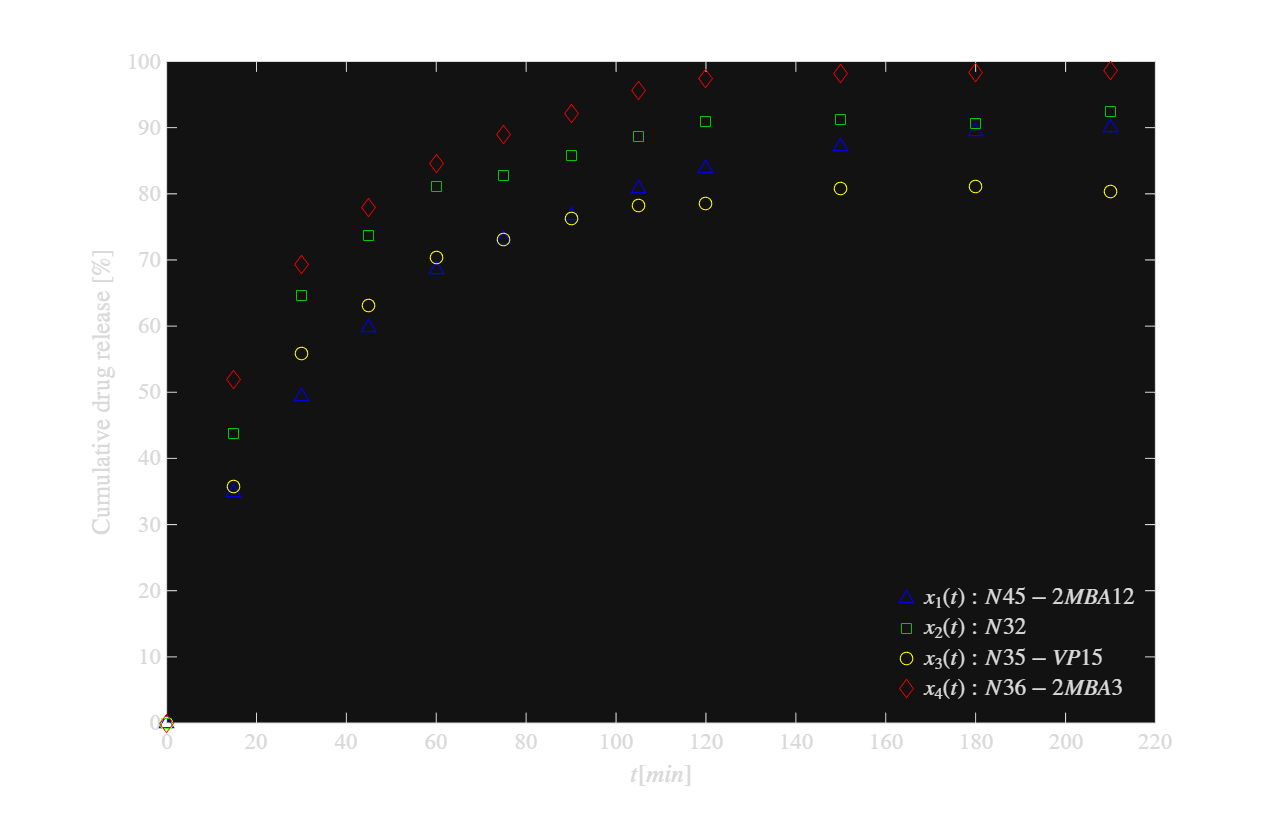

plotsys(t,x1,x2,x3,x4);

## Regresión no lineal, bioestadísticos y experimentación *in silico*

labels = {'x1(t):N45-2MBA12','x2(t):N32','x3(t):N35-VP15','x4(t):N36-2MBA3'};
xo = [x1,x2,x3,x4]; s = size(xo);

### Función de Pepas

n0 = 0.1; k0 = 0.1;
for i = 1:4
    disp(['Resultados para el Hidrogel: ', string(labels(i))]);
    mdl = peppas(t,xo(:,i),[n0;k0]);
    xp(:,i) = mdl.Fitted; disp(' ');
end

    "Resultados para el Hidrogel: "    "x1(t):N45-2MBA12"



Cantidad de datos: 12
Cantidad de parametros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
    Parameters    Estimate      SE         MoE              CI95             Pvalue  
    __________    ________    _______    ________    __________________    __________

      {'k'}        17.851      2.1827      4.8633     12.987     22.714     9.701e-06
      {'n'}       0.31534     0.02605    0.058043    0.25729    0.37338    2.6916e-07

R-cuadrada ordinaria: 0.97994
Suma residual de cuadrados: 159.0183
Criterio de informacion de Akaike ajustado (n/k<40): 70.3972



    "Resultados para el Hidrogel: "    "x2(t):N32"



Cantidad de datos: 12
Cantidad de parametros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

      {'k'}        30.657       4.3337      9.6562     21.001     40.313    3.3994e-05
      {'n'}       0.21929     0.030594    0.068168    0.15112    0.28746    3.0399e-05

R-cuadrada ordinaria: 0.96271
Suma residual de cuadrados: 304.6607
Criterio de informacion de Akaike ajustado (n/k<40): 78.1994



    "Resultados para el Hidrogel: "    "x3(t):N35-VP15"



Cantidad de datos: 12
Cantidad de parametros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

      {'k'}        25.032       3.9256      8.7467     16.285     33.779    8.0703e-05
      {'n'}       0.23432     0.033851    0.075424    0.15889    0.30974     4.083e-05

R-cuadrada ordinaria: 0.95687
Suma residual de cuadrados: 279.569
Criterio de informacion de Akaike ajustado (n/k<40): 77.168



    "Resultados para el Hidrogel: "    "x4(t):N36-2MBA3"



Cantidad de datos: 12
Cantidad de parametros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

      {'k'}         34.36       3.7801      8.4226     25.938     42.783    3.7845e-06
      {'n'}       0.21006     0.023849    0.053138    0.15692     0.2632    5.0219e-06

R-cuadrada ordinaria: 0.97625
Suma residual de cuadrados: 216.4276
Criterio de informacion de Akaike ajustado (n/k<40): 74.0961



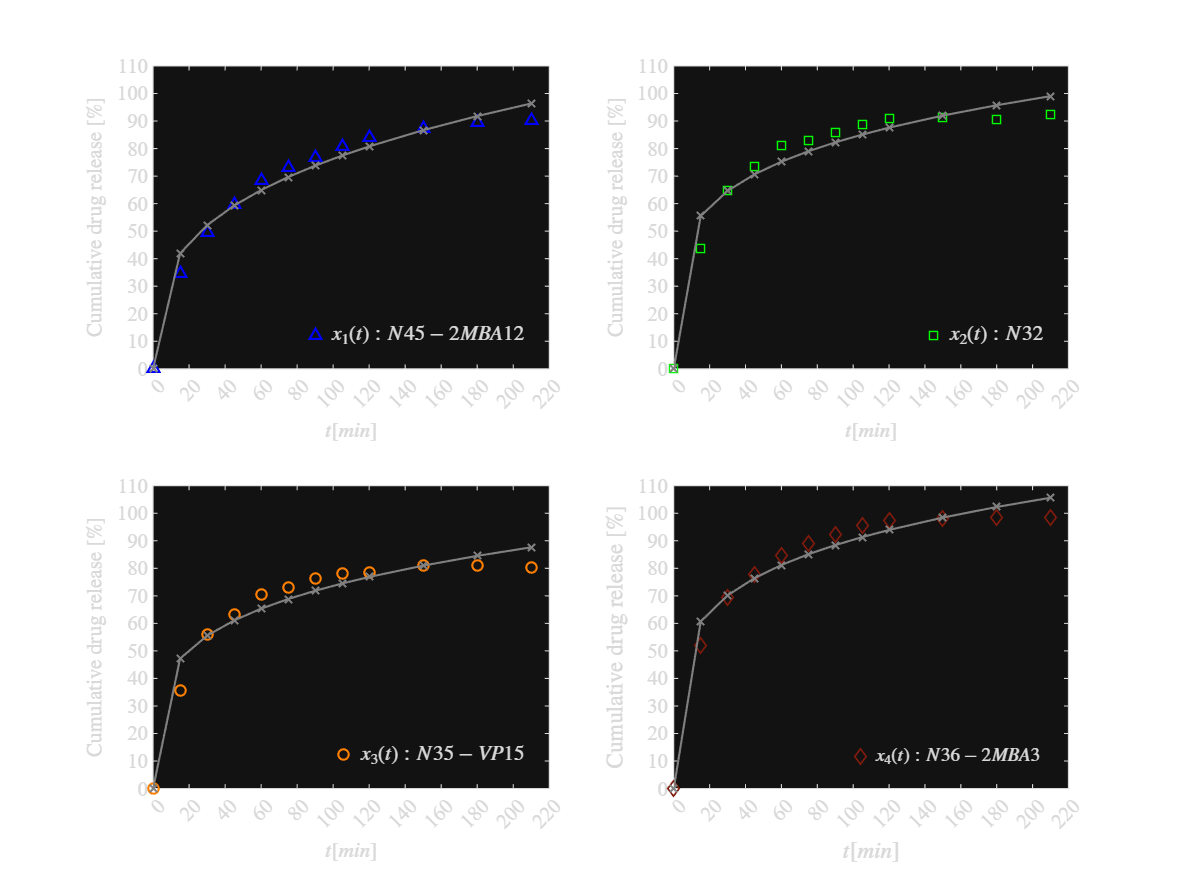

plotresults(t,xo,xp); exportgraphics(gcf,'peppas.pdf','ContentType', 'vector')

### Función farmacocinética de primer orden

beta0 = 100; k0 = 0.01; xfc = zeros(s(1),s(2));
for i = 1:4
    disp(['Resultados pra el Hidrogel: ', string(labels(i))]);
    mdl = farmacocinetica(t,xo(:,i),[beta0;k0]);
    xfc(:,i) = mdl.Fitted; disp(' ');
end

    "Resultados pra el Hidrogel: "    "x1(t):N45-2MBA12"



Cantidad de datos: 12
Cantidad de parametros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
    Parameters    Estimate       SE           MoE              CI95              Pvalue  
    __________    ________    _________    _________    ___________________    __________

     {'beta'}       88.032       1.4806        3.299     84.733      91.331    4.3998e-14
     {'k'   }     0.026125    0.0015553    0.0034655    0.02266    0.029591    1.1734e-08

R-cuadrada ordinaria: 0.99083
Suma residual de cuadrados: 72.6818
Criterio de informacion de Akaike ajustado (n/k<40): 61.0021



    "Resultados pra el Hidrogel: "    "x2(t):N32"



Cantidad de datos: 12
Cantidad de parametros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
    Parameters    Estimate       SE           MoE              CI95             Pvalue  
    __________    ________    _________    _________    __________________    __________

     {'beta'}      90.212       0.81191        1.809     88.403     92.021    8.5496e-17
     {'k'   }      0.0404     0.0017098    0.0038096    0.03659    0.04421    4.1818e-10

R-cuadrada ordinaria: 0.99554
Suma residual de cuadrados: 36.4105
Criterio de informacion de Akaike ajustado (n/k<40): 52.7073



    "Resultados pra el Hidrogel: "    "x3(t):N35-VP15"



Cantidad de datos: 12
Cantidad de parametros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
    Parameters    Estimate       SE           MoE              CI95              Pvalue  
    __________    ________    _________    _________    ___________________    __________

     {'beta'}       79.765      0.61862       1.3784     78.386      81.143    1.9323e-17
     {'k'   }     0.037494    0.0013033    0.0029039    0.03459    0.040398     5.997e-11

R-cuadrada ordinaria: 0.99696
Suma residual de cuadrados: 19.6983
Criterio de informacion de Akaike ajustado (n/k<40): 45.3354



    "Resultados pra el Hidrogel: "    "x4(t):N36-2MBA3"



Cantidad de datos: 12
Cantidad de parametros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
    Parameters    Estimate       SE          MoE               CI95              Pvalue  
    __________    ________    ________    _________    ____________________    __________

     {'beta'}       96.311       1.386       3.0882      93.223      99.399    9.2873e-15
     {'k'   }     0.042064    0.002921    0.0065085    0.035555    0.048572    5.1715e-08

R-cuadrada ordinaria: 0.98793
Suma residual de cuadrados: 109.9482
Criterio de informacion de Akaike ajustado (n/k<40): 65.9691



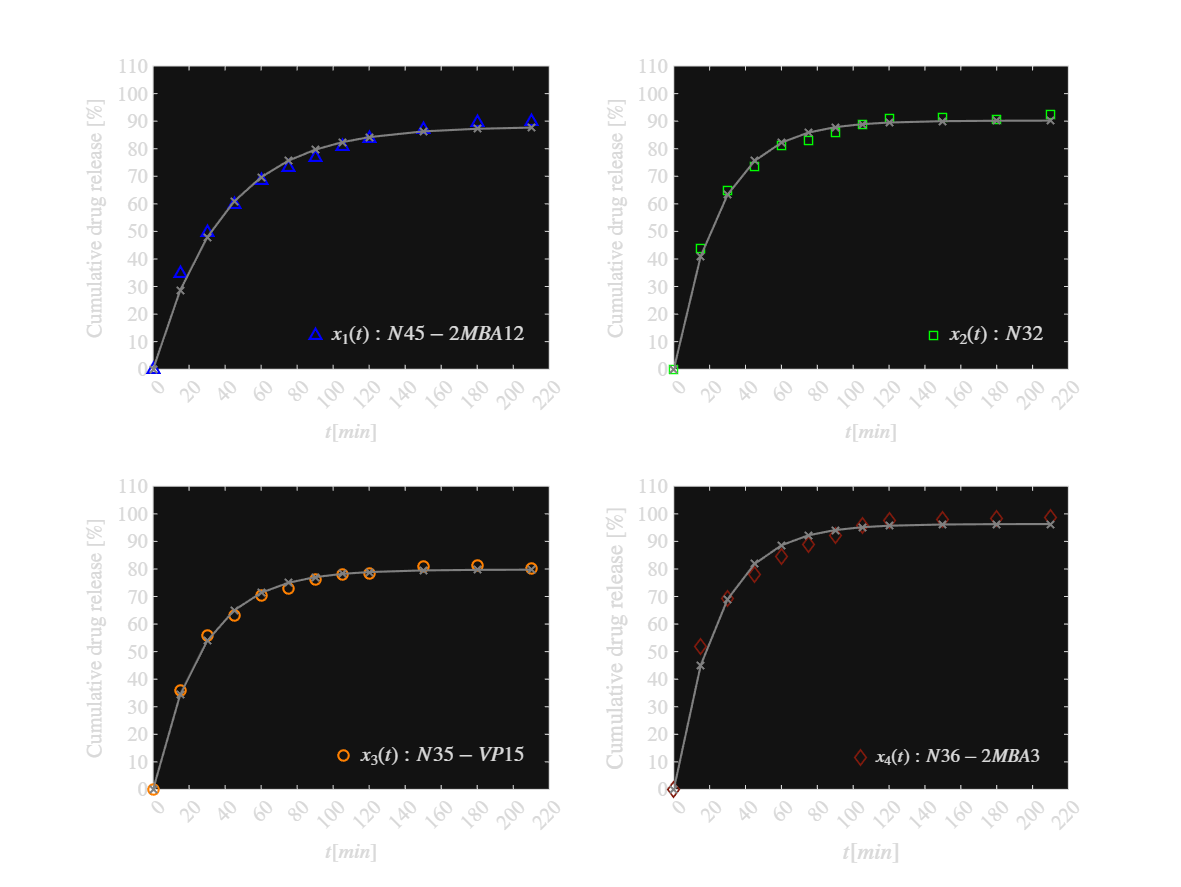

plotresults(t,xo,xfc); exportgraphics(gcf,'farmacocinetica.pdf','ContentType', 'vector')

### Eureqa: Función en el tiempo

rho1 = 11.6525804118489; rho2 = 0.371756060606788; xe1 = zeros(s(1),s(2));
for i = 1:4
    disp(['Resultados para el Hidrogel: ', string(labels(i))]);
    mdl_eureqa = eureqafunction(t, xo(:,i), [rho1; rho2]);
    xe1(:,i) = mdl_eureqa.Fitted; 
end

    "Resultados para el Hidrogel: "    "x1(t):N45-2MBA12"



Cantidad de datos: 12
Cantidad de parametros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

      {'k1'}       11.258      0.22602     0.50361     10.755     11.762    2.5697e-13
      {'k2'}      0.34015     0.019513    0.043478    0.29667    0.38363    8.1891e-09

R-cuadrada ordinaria: 0.99636
Suma residual de cuadrados: 28.8603
Criterio de informacion de Akaike ajustado (n/k<40): 49.9186



    "Resultados para el Hidrogel: "    "x2(t):N32"



Cantidad de datos: 12
Cantidad de parametros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

      {'k1'}       14.615      0.26392     0.58804     14.027     15.203    8.9387e-14
      {'k2'}      0.57705     0.022785    0.050768    0.52628    0.62781    2.1117e-10

R-cuadrada ordinaria: 0.99518
Suma residual de cuadrados: 39.349
Criterio de informacion de Akaike ajustado (n/k<40): 53.6386



    "Resultados para el Hidrogel: "    "x3(t):N35-VP15"



Cantidad de datos: 12
Cantidad de parametros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

      {'k1'}       12.576      0.26978      0.6011     11.975     13.178    4.9711e-13
      {'k2'}      0.48532     0.023291    0.051895    0.43343    0.53722    1.4366e-09

R-cuadrada ordinaria: 0.99366
Suma residual de cuadrados: 41.1166
Criterio de informacion de Akaike ajustado (n/k<40): 54.1659



    "Resultados para el Hidrogel: "    "x4(t):N36-2MBA3"



Cantidad de datos: 12
Cantidad de parametros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
    Parameters    Estimate      SE        MoE             CI95             Pvalue  
    __________    ________    ______    ________    _________________    __________

      {'k1'}       15.752     0.1251     0.27874    15.473     16.031      2.45e-17
      {'k2'}      0.62497     0.0108    0.024065    0.6009    0.64903    5.7672e-14

R-cuadrada ordinaria: 0.99903
Suma residual de cuadrados: 8.8414
Criterio de informacion de Akaike ajustado (n/k<40): 35.7224



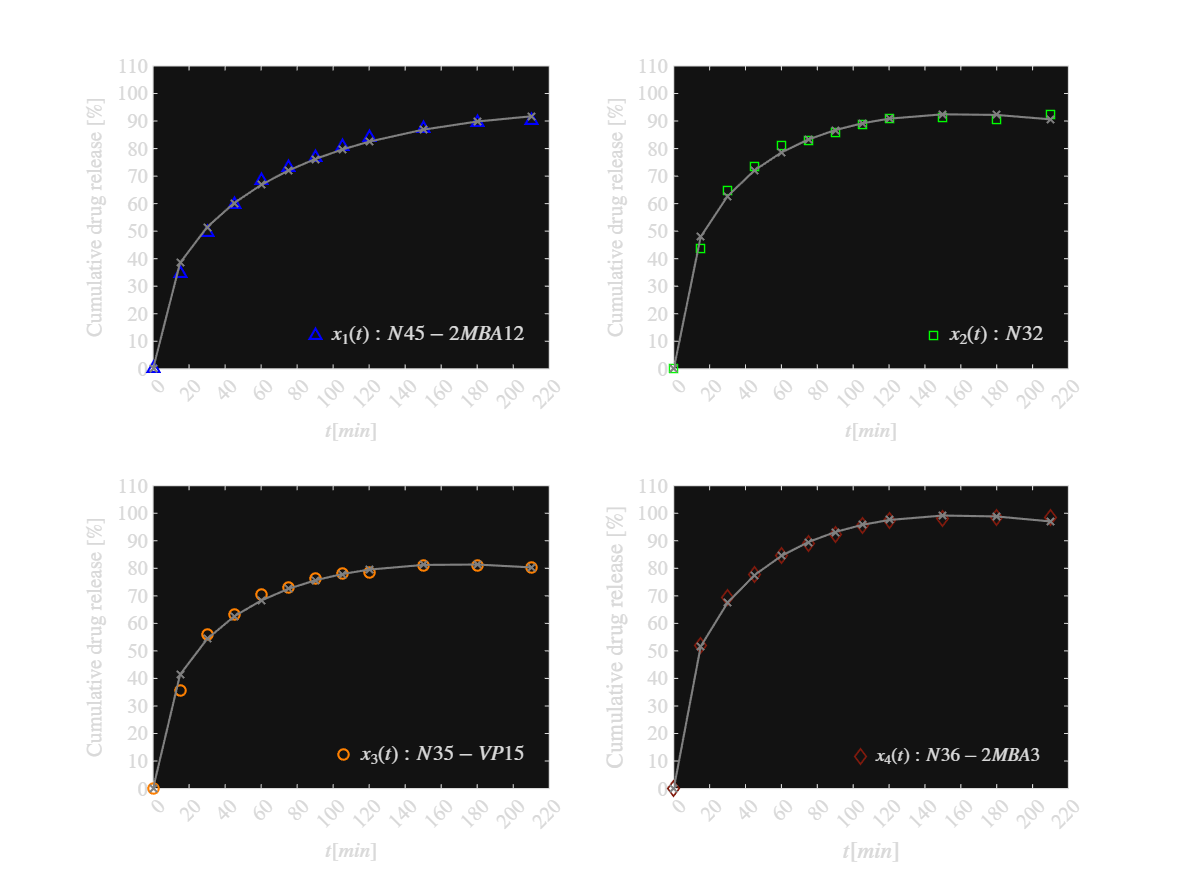

plotresults(t,xo,xe1); exportgraphics(gcf,'eureqafunction.pdf','ContentType', 'vector')

### Eureqa: Farmacocinética de primer orden

rho1 = 2.31822897337454; rho2 = 0.0260578543039873; xode = zeros(s(1),s(2));
for i = 1:4 
    disp(['Resultados para el Hidrogel: ', string(labels(i))]); 
    mdl_ode = eureqadiferencial(t, xo(:,i), [rho1; rho2]);
    xode(:,i) = mdl_ode.Fitted;
end

    "Resultados para el Hidrogel: "    "x1(t):N45-2MBA12"



Cantidad de datos: 12
Cantidad de parametros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
    Parameters    Estimate       SE           MoE              CI95              Pvalue  
    __________    ________    _________    _________    ___________________    __________

      {'a'}         2.2999      0.11054      0.24629     2.0536      2.5461    1.4576e-09
      {'b'}       0.026125    0.0015554    0.0034657    0.02266    0.029591    1.1738e-08

R-cuadrada ordinaria: 0.99083
Suma residual de cuadrados: 72.6818
Criterio de informacion de Akaike ajustado (n/k<40): 61.0021



    "Resultados para el Hidrogel: "    "x2(t):N32"



Cantidad de datos: 12
Cantidad de parametros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
    Parameters    Estimate       SE           MoE              CI95             Pvalue  
    __________    ________    _________    _________    __________________    __________

      {'a'}        3.6446       0.13623      0.30354      3.341     3.9481    1.2297e-10
      {'b'}        0.0404     0.0017098    0.0038097    0.03659    0.04421    4.1825e-10

R-cuadrada ordinaria: 0.99554
Suma residual de cuadrados: 36.4105
Criterio de informacion de Akaike ajustado (n/k<40): 52.7073



    "Resultados para el Hidrogel: "    "x3(t):N35-VP15"



Cantidad de datos: 12
Cantidad de parametros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
    Parameters    Estimate       SE           MoE              CI95              Pvalue  
    __________    ________    _________    _________    ___________________    __________

      {'a'}         2.9907     0.090694      0.20208     2.7886      3.1928    1.5522e-11
      {'b'}       0.037494    0.0013033    0.0029039    0.03459    0.040398    5.9978e-11

R-cuadrada ordinaria: 0.99696
Suma residual de cuadrados: 19.6983
Criterio de informacion de Akaike ajustado (n/k<40): 45.3354



    "Resultados para el Hidrogel: "    "x4(t):N36-2MBA3"



Cantidad de datos: 12
Cantidad de parametros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

      {'a'}         4.0512      0.25002      0.55707      3.4941      4.6083    1.6616e-08
      {'b'}       0.042064    0.0029211    0.0065086    0.035555    0.048572    5.1724e-08

R-cuadrada ordinaria: 0.98793
Suma residual de cuadrados: 109.9482
Criterio de informacion de Akaike ajustado (n/k<40): 65.9691



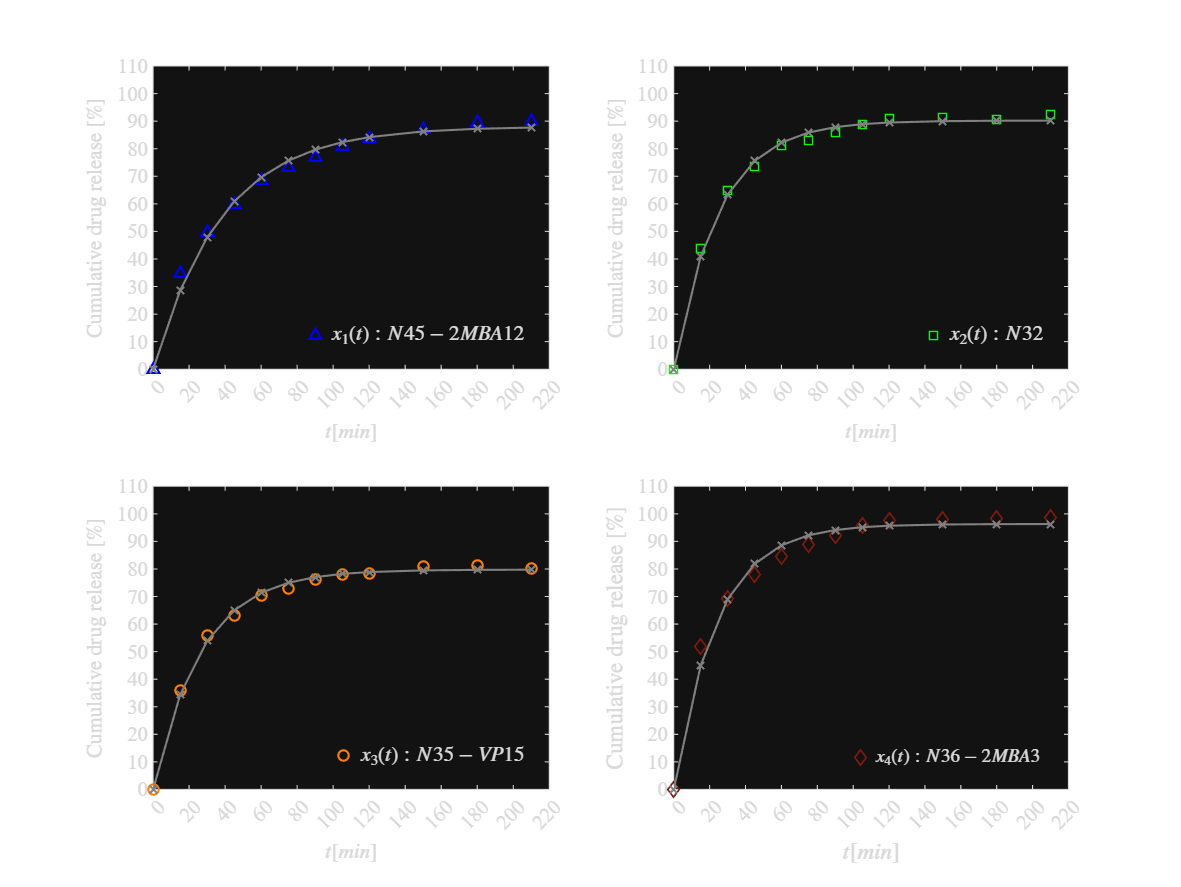

plotresults(t,xo,xode); exportgraphics(gcf,'eureqaODE.pdf','ContentType', 'vector')

## Funciones

function plotsys(t,x1,x2,x3,x4)
    figure('Color','w','Units','centimeters','Position',[2 2 22 14])
    FS = 11;
    MS = 6;
    hold on; box on;
    plot(t,x1,'^-','Color','b','LineStyle','none','MarkerSize',MS)
    plot(t,x2,'s-','Color','g','LineStyle','none','MarkerSize',MS)
    plot(t,x3,'o-','Color','y','LineStyle','none','MarkerSize',MS)
    plot(t,x4,'d-','Color','r','LineStyle','none','MarkerSize',MS)
    xlim([0 220])
    ylim([0 100])
    xlabel('$t [min]$','Interpreter','Latex','FontSize',FS)
    ylabel('Cumulative drug release [\%]','Interpreter','Latex','FontSize',FS)
    L = legend('$x_1(t): N45-2MBA12$','$x_2(t): N32$','$x_3(t): N35-VP15$','$x_4(t): N36-2MBA3$');
    set(L,'Interpreter','Latex','FontSize',FS,'Box','Off','Location','SouthEast');
    set(gca,'FontName','Times New Roman','FontSize',FS)

    exportgraphics(gcf,'data.pdf','ContentType', 'vector')
end

function plotresults(t,xo,xp)
    set(figure(), 'color', 'w')
    FS = 12; 
    set(gcf, 'Units', 'Centimeters', 'Position', [1,1,20,15])
    set(gca,'FontName','Times New Roman','FontSize',FS)

    subplot(2,2,1); hold on; box on; grid off; fontsize(10,"points"); set(gca, 'FontName', 'Times New Roman')
    plot(t, xo(:,1), '^-', 'LineWidth', 1,'LineStyle','none', 'MarkerSize', 5, 'Color', [0, 0, 1])
    plot(t, xp(:,1), '-x', 'LineWidth', 1, 'MarkerSize', 5, 'Color', [0.5, 0.5, 0.5])
    xlabel('$t [min]$','Interpreter','Latex')
    ylabel('Cumulative drug release [\%]','Interpreter','Latex')
    xlim([0 220]); xticks(0:20:220)
    ylim([0 110]); yticks(0:10:110)
    L = legend('$x_1(t): N45-2MBA12$');
    set(L,'Interpreter','Latex','Box','Off','Location','SouthEast');

    subplot(2,2,2); hold on; box on; grid off; fontsize(10,"points"); set(gca, 'FontName', 'Times New Roman')
    plot(t, xo(:,2), 's-', 'LineWidth', 1,'LineStyle','none', 'MarkerSize', 5, 'Color', [0, 1, 0])
    plot(t, xp(:,2), '-x', 'LineWidth', 1, 'MarkerSize', 5, 'Color', [0.5, 0.5, 0.5])
    xlabel('$t [min]$','Interpreter','Latex')
    ylabel('Cumulative drug release [\%]','Interpreter','Latex')
    xlim([0 220]); xticks(0:20:220)
    ylim([0 110]); yticks(0:10:110)
    L = legend('$x_2(t): N32$');
    set(L,'Interpreter','Latex','Box','Off','Location','SouthEast');

    subplot(2,2,3); hold on; box on; grid off; fontsize(10,"points"); set(gca, 'FontName', 'Times New Roman')
    plot(t, xo(:,3), 'o-', 'LineWidth', 1,'LineStyle','none', 'MarkerSize', 5, 'Color', [1, 0.5, 0])
    plot(t, xp(:,3), '-x', 'LineWidth', 1, 'MarkerSize', 5, 'Color', [0.5, 0.5, 0.5])
    xlabel('$t [min]$','Interpreter','Latex')
    ylabel('Cumulative drug release [\%]','Interpreter','Latex')
    xlim([0 220]); xticks(0:20:220)
    ylim([0 110]); yticks(0:10:110)
    L = legend('$x_3(t): N35-VP15$');
    set(L,'Interpreter','Latex','Box','Off','Location','SouthEast');

    subplot(2,2,4); hold on; box on; grid off; fontsize(10,"points"); set(gca, 'FontName', 'Times New Roman')
    plot(t, xo(:,4), 'd-', 'LineWidth', 1,'LineStyle','none', 'MarkerSize', 5, 'Color', [0.5, 0.1, 0.05])
    plot(t, xp(:,4), '-x', 'LineWidth', 1, 'MarkerSize', 5, 'Color', [0.5, 0.5, 0.5])
    xlabel('$t [min]$','Interpreter','Latex')
    ylabel('Cumulative drug release [\%]','Interpreter','Latex')
    xlim([0 220]); xticks(0:20:220)
    ylim([0 110]); yticks(0:10:110)
    L = legend('$x_4(t): N36-2MBA3$');
    set(L,'Interpreter','Latex','Box','Off','Location','SouthEast');
    
end

### Modelos matemáticos y bioestadísticos

function biostats(mdl, Parameters)
        Estimate = table2array(mdl.Coefficients(:,1));
        SE = table2array(mdl.Coefficients(:,2));
        Pvalue = table2array(mdl.Coefficients(:,4));
        alpha = 0.05;
        CI95 = coefCI(mdl,alpha);
        dof = mdl.DFE;
        tval = tinv(1-alpha/2,dof);
        MoE = SE*tval;
        n_datos = mdl.NumObservations; % Cantidad de datos
        k_params = mdl.NumCoefficients; % Cantidad de parámetros 
        
        Results = table(Parameters,Estimate,SE,MoE,CI95,Pvalue);
        disp(['Cantidad de datos: ', num2str(n_datos)])
        disp(['Cantidad de parametros: ', num2str(k_params)])
        disp(['Grados de libertad: ',num2str(dof)])
        disp(['Valor t-student: ',num2str(tval)])
        disp(['Alpha: ',num2str(alpha)])
        disp(''); disp(Results)
        
        R2o = mdl.Rsquared.Ordinary;
        SSE = mdl.SSE;
        AICc = mdl.ModelCriterion.AICc;
        
        fprintf(['R-cuadrada ordinaria: ', num2str(R2o)]);
        fprintf(['\nSuma residual de cuadrados: ', num2str(SSE)]);
        fprintf(['\nCriterio de informacion de Akaike ajustado (n/k<40): ', num2str(AICc), '\n\n']);
end 

function mdl = peppas(to,xo,par)

    function x = model(par,t)
        k = par(1); n = par(2);
        x = k*t.^n;
    end
    
    mdl = fitnlm(to,xo,@model,par);
    Parameters = {'k'; 'n'};
    biostats(mdl,Parameters)

end

function mdl = farmacocinetica(to, xo, par)

    function x = model(par, t)
        beta = par(1); 
        k = par(2);
        x = beta * (1 - exp(-k * t)); 
    end
    
    mdl = fitnlm(to, xo, @model, par);
    Parameters = {'beta'; 'k'};
    biostats(mdl, Parameters);

end

function mdl = eureqafunction(to, xo, par)

    function x = model(par, t)
        k1 = par(1); 
        k2 = par(2);
        x = k1 * sqrt(t) - k2 * t; 
    end

    mdl = fitnlm(to, xo, @model, par);
    Parameters = {'k1'; 'k2'};
    biostats(mdl, Parameters);

end

function mdl = eureqadiferencial(to, xo, par)

    function xi = model(par, ta)
            a = par(1); b = par(2);
            dt = 1E-1;
            time = (0:dt:max(ta))';
            x = zeros(length(time),1); 
            x(1) = 0;
            n_steps = round(max(ta)/dt);
    
            % Método de Heun
            for i = 1:n_steps 
                fx = f(x(i));
                xn = x(i) + fx*dt;
                fxn = f(xn);
                x(i+1) = x(i) + (fx + fxn)*dt/2;
            end
            
            % EDO
            function dx = f(x_1)
                dx = a - b*x_1;
            end
            xi = interp1(time, x, ta, 'linear');
        end
    
        mdl = fitnlm(to, xo, @model, par);
        Parameters = {'a'; 'b'};
        biostats(mdl, Parameters);
        
end